# Installation on Large Platforms

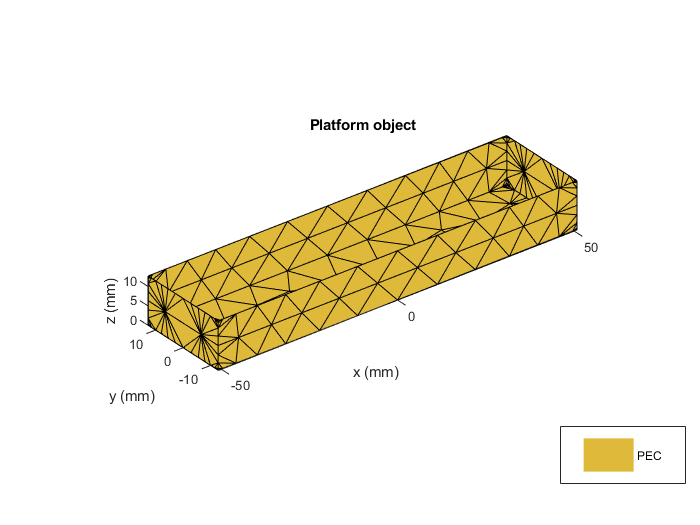

base = platform('FileName', 'rectcavity.stl', 'Units', 'in');
show(base);

`Example code to design the array and compute the pattern. Results are pre-stored to speed up execution.`

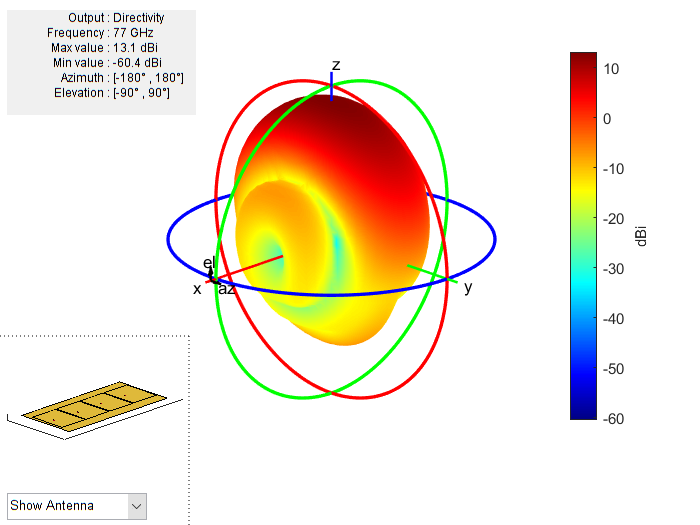

load('patchArrayMetalPattern.mat');
pattern(L, 77e9);

Tilt the antenna array, to be positioned on the front of the cavity pointing outwards. 

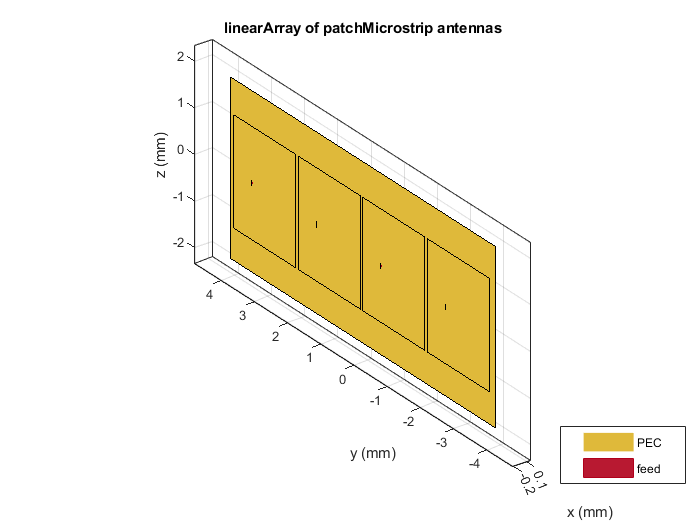

L.TiltAxis = [0 0 1;0 1 0];
L.Tilt = [90; -90];
show(L)

You can load pre-computed results to speed up execution.

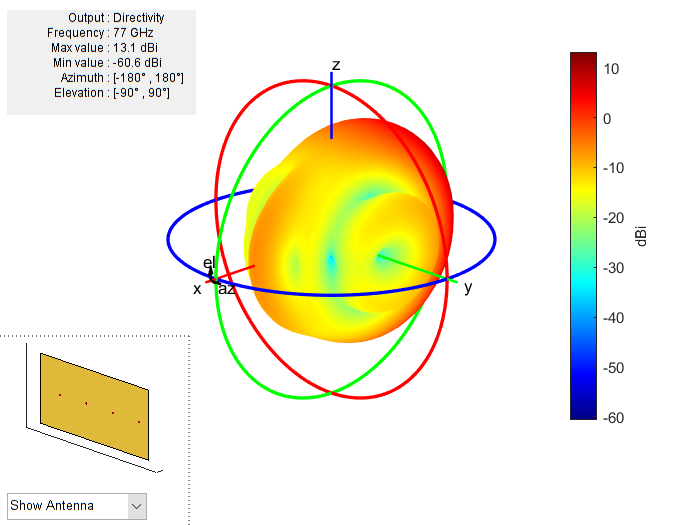

pattern(L, 77e9);

Install the antenna array on the front of the cavity.

base = platform('FileName', 'rectcavity.stl', 'Units', 'in');
array = installedAntenna;
array.Platform = base;
array.Element = L;
array.ElementPosition = [-0.051, 0, 0.005]
show(array);

You can load pre-computed results to speed up execution.

pattern(array, 77e9);